Leer los datos almacenados

A = readmatrix("M10hz.txt");
B = readmatrix("10hz.txt");
C= readmatrix("10hz.txt");
n=0;
b=0;
i=1;
j=0;
k=200;
p = zeros(100,1);
pk = zeros(100,1);
V = [p;pk];
V1 = [p;pk];

Corrigiendo fase

while n<1
   if (C(i)==2.48 || j==1)
       b=b+1;
       V(b)=C(i);
       j=1;
       if (b>200)
          n=10;
       end
   end
   i=i+1;
end

nn

n=0;
b=0;
i=1;
j=0;
while n<1
    if (A(i)==2.5 || j==1)
       b=b+1;
       V1(b)=A(i);
       j=1;
       if (b>200)
          n=10;
       end
   end
   i=i+1;
end

kkk

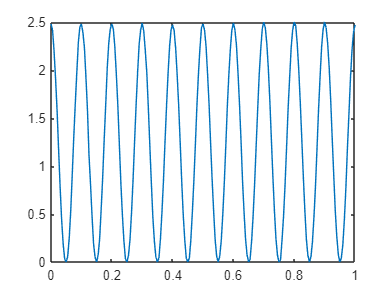

Ts=1/200; % Periodo de muestreo
nT=0:Ts:1;
plot(nT,V)

Hacer PSNR

peaksnr = psnr(V,V1)

peaksnr = 29.3227

Hacer MSE

err = immse(V,V1)

err = 0.0012